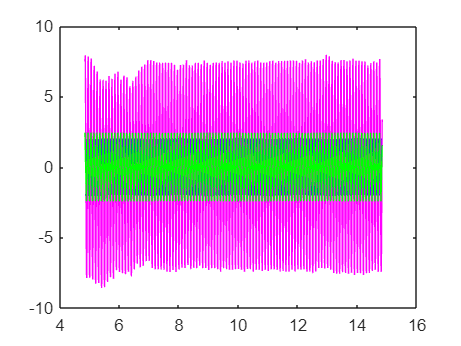

clc, clearvars

%declarando variáveis
char inputFile outPutFile;

% inputFile = input("Enter file name (without the extension): ", 's');
% outputFile = input("Enter file name (without the extension): ", 's');

% adicionando o arquivo
inputFile = 'sqrf1000a200Ent';
outputFile = 'sqrf1000a200Sai';

%ajustando os dados para matrizes de tempo e amplitude
input = importdata(inputFile + ".mat");
inputTime = input.([inputFile '_Time']);
inputAmplitude = input.([inputFile '_Value']);

output = importdata(outputFile + ".mat");
outputTime = output.([outputFile '_Time']);
outputAmplitude = output.([outputFile '_Value']);

%gráfico todo
plot(inputTime, inputAmplitude,'b')
hold on;
plot(outputTime, outputAmplitude(:,1),'m',outputTime, outputAmplitude(:,2),'g')
hold off;

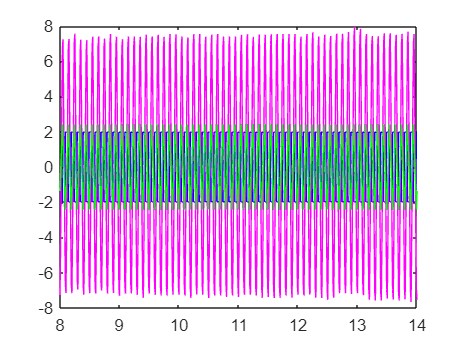


%escolhendo a parte de interesse
startTime = 8;
endTime = 14;
startIndex = find(inputTime >= startTime, 1);
endIndex = find(inputTime >= endTime, 1);

inputTimeRange = inputTime(startIndex:endIndex);
inputAmplitudeRange = inputAmplitude(startIndex:endIndex);

outputTimeRange = outputTime(startIndex:endIndex,:);
outputAmplitudeRange = outputAmplitude(startIndex:endIndex,:);

%gráfico na parte de interesse
plot(inputTimeRange,inputAmplitudeRange,'b')
hold on;
plot(outputTimeRange,outputAmplitudeRange(:,1),'m')
plot(outputTimeRange,outputAmplitudeRange(:,2),'g')
hold off;

%vamos fazer a fft dos sinais

int32 N;
N = length(inputTimeRange);

% frequency = zeros(length(inputTimeRange) -1,1);
%
% for i = 1:(length(inputTimeRange) -1)
%     frequency(i) = 1/(inputTimeRange(i+1) - inputTimeRange(i));
% end
%
% for i = 1:length(frequency)
%     frequency(i) = i*frequency(i);
% end


inputFft = fft(inputAmplitudeRange);
outputFft = fft(outputAmplitudeRange);

magnitudeResponse = abs(outputFft./inputFft);
phaseResponse = angle(outputFft./inputFft);

% %Plotando o diagrama de Bode
% figure;
%
% semilogx(frequency,20*log10(magnitudeResponse(1:length(frequency),1)),'m')
% hold on
% semilogx(frequency,20*log10(magnitudeResponse(1:length(frequency),2)),'g')
% grid on
% hold off

% semilogx(frequency, phaseResponse(1:length(frequency),1),'m')
% hold on
% grid on
% semilogx(frequency, phaseResponse(1:length(frequency),2),'g')
% hold off


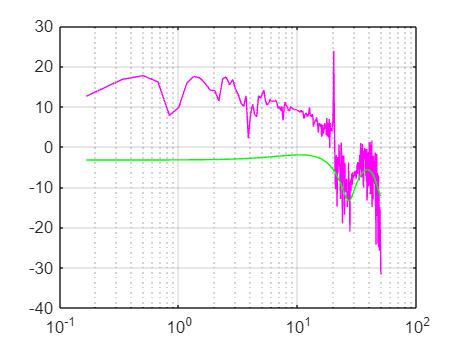

frequencySample = 1/(inputTimeRange(2) - inputTimeRange(1));
frequencies = frequencySample*(0:(N/2))/N;

figure;

semilogx(frequencies,20*log10(magnitudeResponse(1:floor(N/2)+1,1)),'m')
hold on
semilogx(frequencies,20*log10(magnitudeResponse(1:floor(N/2)+1,2)),'g')
hold off
grid on

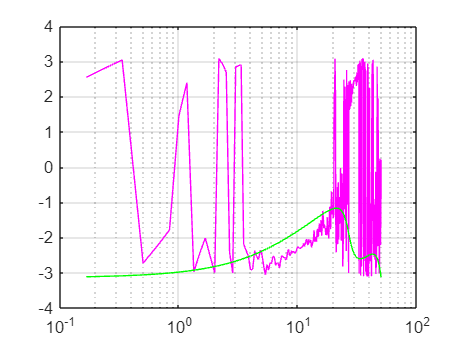


semilogx(frequencies, phaseResponse(1:floor(N/2)+1,1),'m')
hold on
grid on
semilogx(frequencies, phaseResponse(1:floor(N/2)+1,2),'g')
hold off

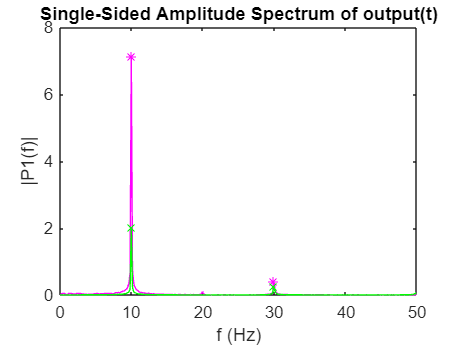

%Vamos tentar filtrar os valores da FFT
P2 = abs(outputFft/N);
P1 = P2(1:floor(N/2)+1,:);
P1(2:end-1) = 2*P1(2:end-1);

plot(frequencies,P1(:,1),'m')
title("Single-Sided Amplitude Spectrum of output(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")
hold on

plot(frequencies,P1(:,2),'g')

% windowSize = 2;
% b = (1/windowSize)*ones(1,windowSize);
% a = 1;
%
% filteredAmplitude = filter(b, a, outputFft)
% fP2 = abs(filteredAmplitude/N);
% fP1 = fP2(1:floor(N/2)+1,:);
% fP1(2:end-1) = 2*fP1(2:end-1);
%
% plot(frequencies,fP1)

amplitudeAverage = sum(P1)/length(P1);

fP1 = zeros(length(P1),2);

for i=1:length(P1)
    if P1(i,1) > 5*amplitudeAverage(1,1)
        fP1(i,1) = P1(i,1);
    else
        fP1(i,1) = 0;
    end
end

for i=1:length(P1)
    if P1(i,2) > 2*amplitudeAverage(1,2)
        fP1(i,2) = P1(i,2);
    else
        fP1(i,2) = 0;
    end
end

peaksfP1  = islocalmax(fP1);

peaksfP1_1out = P1(peaksfP1(:,1),1);
peaksfP1_2out = P1(peaksfP1(:,2),2);

plot(frequencies(peaksfP1(:,1)),peaksfP1_1out,'m*')
plot(frequencies(peaksfP1(:,2)),peaksfP1_2out,'gx')
hold off
title("Single-Sided Amplitude Spectrum of output(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

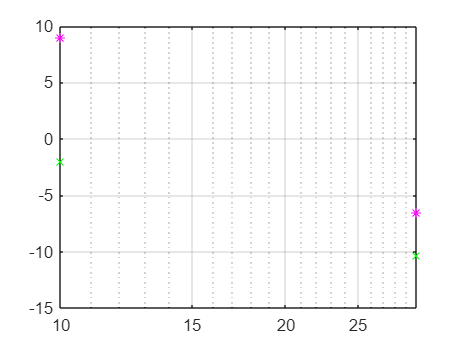

magnitudeResponse = abs(outputFft./inputFft);
phaseResponse = angle(outputFft./inputFft);

filteredMagnitudeResponse = magnitudeResponse(1:floor(N/2)+1,:).*peaksfP1;
filteredPhaseResponse = phaseResponse(1:floor(N/2)+1,:).*peaksfP1;

figure;

semilogx(frequencies,20*log10(filteredMagnitudeResponse(:,1)),'m*')
hold on
semilogx(frequencies,20*log10(filteredMagnitudeResponse(:,2)),'gx')
hold off
grid on

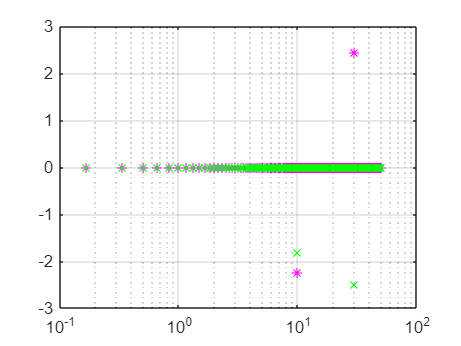


semilogx(frequencies, filteredPhaseResponse(:,1),'m*')
hold on
grid on
semilogx(frequencies, filteredPhaseResponse(:,2),'gx')
hold off

% % Find indices of non-zero points
% nonzeroFMRInd = find(filteredMagnitudeResponse(:, 1) ~= 0 & filteredMagnitudeResponse(:, 2) ~= 0);
% nonzeroFPRInd = find(filteredPhaseResponse(:, 1) ~= 0 & filteredPhaseResponse(:, 2) ~= 0);
% 
% % Filter out (0,0) point
% nonZeroFilteredMR = filteredMagnitudeResponse(nonzeroFMRInd, :);
% nonZeroFilteredPR = filteredPhaseResponse(nonzeroFPRInd, :);
% 
% figure;
% 
% semilogx(frequencies,20*log10(nonZeroFilteredMR(:,1)),'m*')
% hold on
% semilogx(frequencies,20*log10(nonZeroFilteredMR(:,2)),'gx')
% hold off
% grid on
% 
% semilogx(frequencies, nonZeroFilteredPR(:,1),'m*')
% hold on
% grid on
% semilogx(frequencies, nonZeroFilteredPR(:,2),'gx')
% hold off

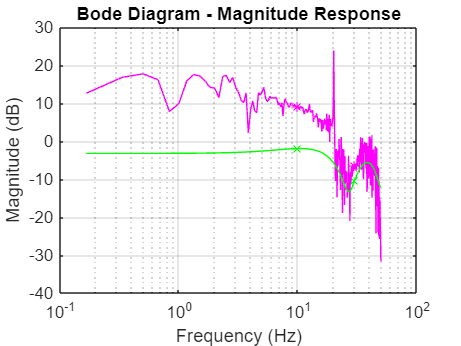

semilogx(frequencies,20*log10(filteredMagnitudeResponse(:,1)),'m*')
hold on
semilogx(frequencies,20*log10(filteredMagnitudeResponse(:,2)),'gx')

semilogx(frequencies,20*log10(magnitudeResponse(1:floor(N/2)+1,1)),'m')
semilogx(frequencies,20*log10(magnitudeResponse(1:floor(N/2)+1,2)),'g')
hold off
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Bode Diagram - Magnitude Response');
grid on

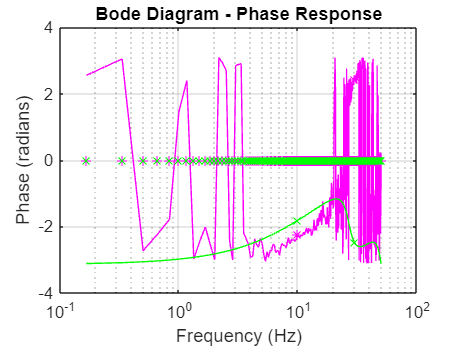


semilogx(frequencies, phaseResponse(1:floor(N/2)+1,1),'m')
hold on
grid on
semilogx(frequencies, phaseResponse(1:floor(N/2)+1,2),'g')

semilogx(frequencies, filteredPhaseResponse(:,1),'m*')
semilogx(frequencies, filteredPhaseResponse(:,2),'gx')
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
title('Bode Diagram - Phase Response');
hold off

freqResponse =  [outputFft(:,1)./inputFft outputFft(:,2)./inputFft]

freqResponse = 601×2 single matrix
  -5.3688 + 0.0000i  -0.6866 + 0.0000i
  -3.5166 + 2.3859i  -0.6864 - 0.0184i
  -6.8402 + 0.6944i  -0.6859 - 0.0368i
  -7.0104 - 3.0761i  -0.6850 - 0.0552i
  -3.8534 - 5.1121i  -0.6838 - 0.0736i
  -0.5240 - 2.3908i  -0.6822 - 0.0919i
   0.3566 + 3.0941i  -0.6802 - 0.1102i
  -4.5604 + 4.2355i  -0.6779 - 0.1284i
  -7.3771 - 1.2421i  -0.6753 - 0.1465i
  -5.4660 - 4.6475i  -0.6723 - 0.1645i


impulseResponse = ifft(freqResponse)

impulseResponse = 601×2 single matrix
   -0.9453   -0.2219
   -0.2100    0.2697
   -0.0052   -0.0000
   -0.0911    0.0000
   -0.1103    0.0000
   -0.0395   -0.0000
    0.0262    0.0000
    0.0247   -0.0000
   -0.0483   -0.0000
   -0.0702    0.0000




impulse_response_double1 = double([inputTimeRange,impulseResponse(:,1)]);
% time = 1:length(impulse_response_double); % Assuming the time axis is just the sample index
% transfer_function = tfest(impulse_response_double1, 9, 'InputDelay', 0, 'OutputDelay', 0, 'TimeUnit', 'seconds')
transfer_function = tfest(impulse_response_double1, 9, 'InputDelay', 0, 'OutputDelay', 0, 'TimeUnit', 'seconds')

transfer_function =
  From input "u1" to output "y1":
     -1.568 s^8 - 0.5029 s^7 - 0.001791 s^6 - 0.005671 s^5 + 0.0007911 s^4 - 4.766e-05 s^3 + 2.664e-06 s^2 - 1.946e-08 s - 4.897e-10
  -------------------------------------------------------------------------------------------------------------------------------------
  s^9 + 0.4985 s^8 + 0.1419 s^7 + 0.01512 s^6 + 0.0008659 s^5 + 3.211e-05 s^4 + 8.527e-07 s^3 + 7.196e-09 s^2 + 5.061e-11 s + 3.309e-13
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 9   Number of zeros: 8
   Number of free coefficients: 18
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                   
Estimated using TFEST on time domain data.
Fit to estimation data: 82.81%            
FPE: 0.09731, MSE: 0.08894                
 


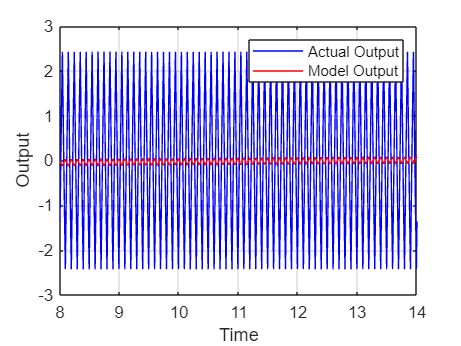

model_output = lsim(transfer_function, inputAmplitudeRange, inputTimeRange);

plot(inputTimeRange, outputAmplitudeRange(:,2), 'b', inputTimeRange, model_output, 'r');
legend('Actual Output', 'Model Output');
xlabel('Time');
ylabel('Output');
grid on